clc;
clear;

Geometries & Initial Definition

AB = 40;
AE = 95;
AF = 280;
BC = 100;
CE = 95;
CH = 65;
DF = 145;
DH = 120;
EH = 95;
ECH = acos((CH^2 + CE^2 - EH^2) / (2 * CH * CE));
CEH = asin(sin(ECH) * CH / EH);
theta20 = deg2rad(135);
omega20 = 1;
T16 = 20;
syms theta2 omega2 alpha2;
syms theta3 omega3 alpha3;
syms theta4 omega4 alpha4;
syms theta5 omega5 alpha5;
syms theta6 omega6 alpha6;
t_range = 0:1/30:4 * pi;

Kinematics

% initial parameters
theta3t = 0.6097;
theta4t = 5.1622;
theta5t = 3.5172;
theta6t = 5.0645;
omega3t = 0.1334;
omega4t = 0.4199;
omega5t = -0.1879;
omega6t = 0.2233;
alpha3t = 0.1006;
alpha4t = 0.3166;
alpha5t = -0.1417;
alpha6t = 0.1684;

theta_values = cell(1, 5);
omega_values = cell(1, 5);
alpha_values = cell(1, 5);

rb = AB .* [cos(theta2), sin(theta2), 0];
re = [AE, 0, 0];
rf = [AF, 0, 0];
rbc = BC .* [cos(theta3), sin(theta3), 0];
rce = CE .* [cos(theta4), sin(theta4), 0];
rch = CH .* [cos(theta4 + ECH), sin(theta4 + ECH), 0];
rdf = DF .* [cos(theta6), sin(theta6), 0];
rdh = DH .* [cos(theta5), sin(theta5), 0];
reh = EH .* [cos(theta4 - pi - CEH), sin(theta4 - pi - CEH), 0];

for t = t_range
    %     alpha2t = 8 * pi / (1000/3 - 500) * t +- 40 * pi / (1000/3 - 500);
    %     omega2t = 4 * pi / (1000/3 - 500) * t^2 - 40 * pi / (1000/3 - 500) * t;
    %     theta2t = 4 * pi / (1000/3 - 500) / 3 * t^3 - 20 * pi / (1000/3 - 500) * t^2 + theta20;
    alpha2t = 0;
    omega2t = omega20;
    theta2t = omega2t * t + theta20;

    eqns_theta = [
            rb + rbc + rce == re;
            reh - rdh + rdf == rf - re;
            ];
    eqns_theta = subs(eqns_theta, theta2, theta2t);
    slv_theta = vpasolve(eqns_theta, [theta3, theta4, theta5, theta6], [theta3t, theta4t, theta5t, theta6t]);
    theta3t = slv_theta.theta3;
    theta4t = slv_theta.theta4;
    theta5t = slv_theta.theta5;
    theta6t = slv_theta.theta6;

    eqns_omega = [
            omega2 * diff(rb) + omega3 * diff(rbc) + omega4 * diff(rce) == 0;
            omega4 * diff(reh) - omega5 * diff(rdh) + omega6 * diff(rdf) == 0;
            ];
    eqns_omega = subs(eqns_omega, [theta2, theta3, theta4, theta5, theta6, omega2], [theta2t, theta3t, theta4t, theta5t, theta6t, omega2t]);
    slv_omega = vpasolve(eqns_omega, [omega3, omega4, omega5, omega6], [omega3t, omega4t, omega5t, omega6t]);
    omega3t = slv_omega.omega3;
    omega4t = slv_omega.omega4;
    omega5t = slv_omega.omega5;
    omega6t = slv_omega.omega6;

    eqns_alpha = [
            alpha2 * diff(rb) + omega2^2 * diff(rb, 2) + alpha3 * diff(rbc) + omega3^2 * diff(rbc, 2) + alpha4 * diff(rce) + omega4^2 * diff(rce, 2) == 0;
            alpha4 * diff(reh) + omega4^2 * diff(reh, 2) - alpha5 * diff(rdh) - omega5^2 * diff(rdh, 2) + alpha6 * diff(rdf) + omega6^2 * diff(rdf, 2) == 0;
            ];
    eqns_alpha = subs(eqns_alpha, [theta2, theta3, theta4, theta5, theta6, omega2, omega3, omega4, omega5, omega6, alpha2], [theta2t, theta3t, theta4t, theta5t, theta6t, omega2t, omega3t, omega4t, omega5t, omega6t, alpha2t]);
    slv_alpha = vpasolve(eqns_alpha, [alpha3, alpha4, alpha5, alpha6], [alpha3t, alpha4t, alpha5t, alpha6t]);
    alpha3t = slv_alpha.alpha3;
    alpha4t = slv_alpha.alpha4;
    alpha5t = slv_alpha.alpha5;
    alpha6t = slv_alpha.alpha6;

    theta_values{1} = [theta_values{1}, theta2t];
    theta_values{2} = [theta_values{2}, theta3t];
    theta_values{3} = [theta_values{3}, theta4t];
    theta_values{4} = [theta_values{4}, theta5t];
    theta_values{5} = [theta_values{5}, theta6t];

    omega_values{1} = [omega_values{1}, omega2t];
    omega_values{2} = [omega_values{2}, omega3t];
    omega_values{3} = [omega_values{3}, omega4t];
    omega_values{4} = [omega_values{4}, omega5t];
    omega_values{5} = [omega_values{5}, omega6t];

    alpha_values{1} = [alpha_values{1}, alpha2t];
    alpha_values{2} = [alpha_values{2}, alpha3t];
    alpha_values{3} = [alpha_values{3}, alpha4t];
    alpha_values{4} = [alpha_values{4}, alpha5t];
    alpha_values{5} = [alpha_values{5}, alpha6t];
end

Plot

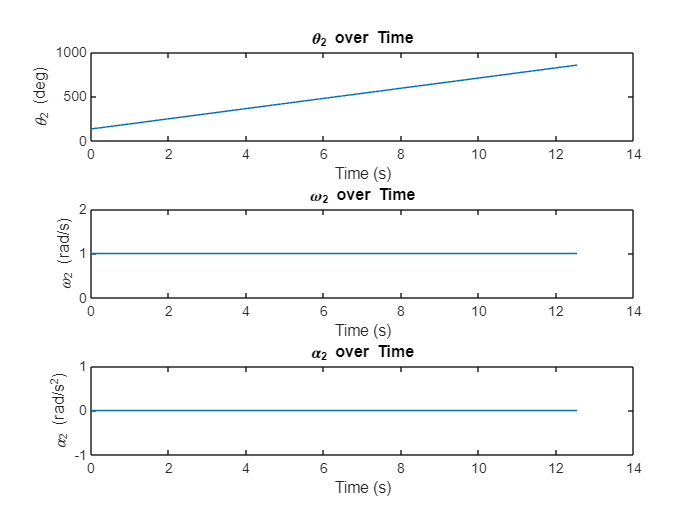

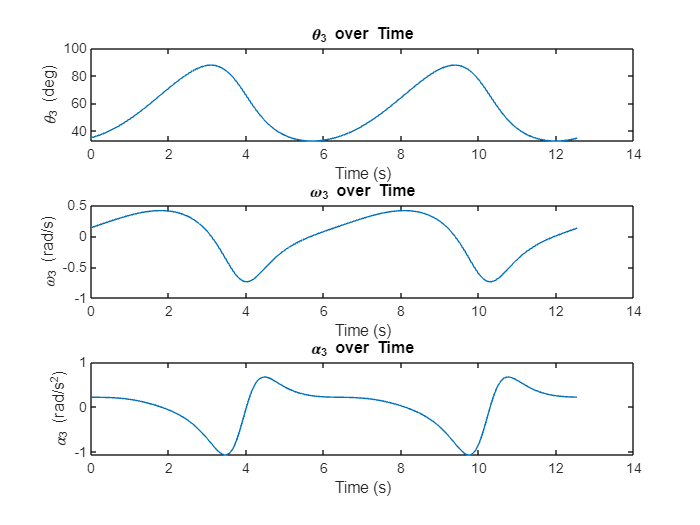

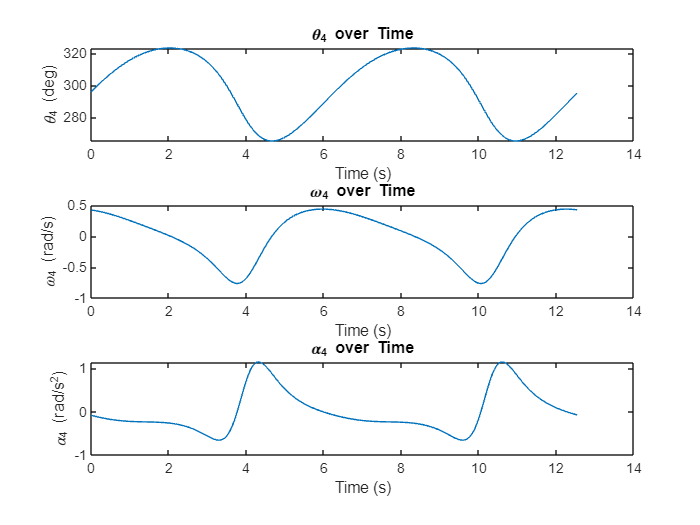

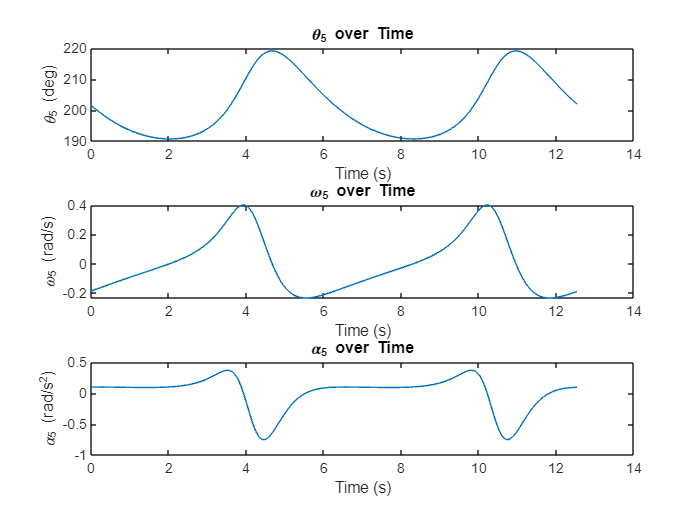

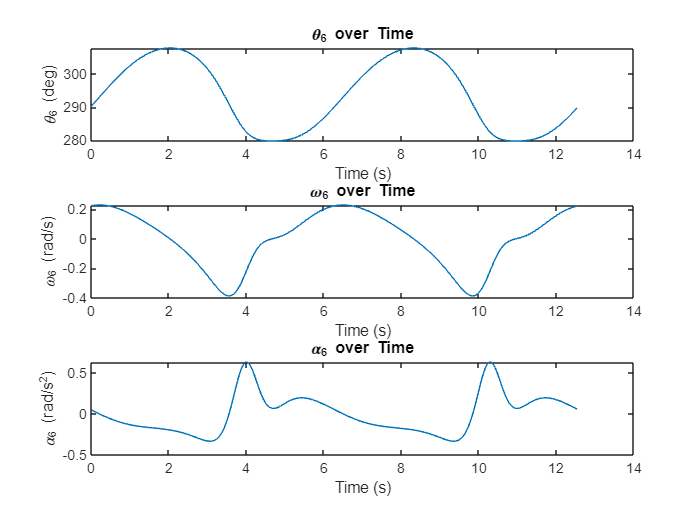

for i = 1:5
    figure;
    % Theta values
    subplot(3, 1, 1);
    plot(t_range, rad2deg(theta_values{i}));
    title(['\theta_', num2str(i + 1), ' over Time']);
    xlabel('Time (s)');
    ylabel(['\theta_', num2str(i + 1), ' (deg)']);

    % Omega values
    subplot(3, 1, 2);
    plot(t_range, omega_values{i});
    title(['\omega_', num2str(i + 1), ' over Time']);
    xlabel('Time (s)');
    ylabel(['\omega_', num2str(i + 1), ' (rad/s)']);

    % Alpha values
    subplot(3, 1, 3);
    plot(t_range, alpha_values{i});
    title(['\alpha_', num2str(i + 1), ' over Time']);
    xlabel('Time (s)');
    ylabel(['\alpha_', num2str(i + 1), ' (rad/s^2)']);
end

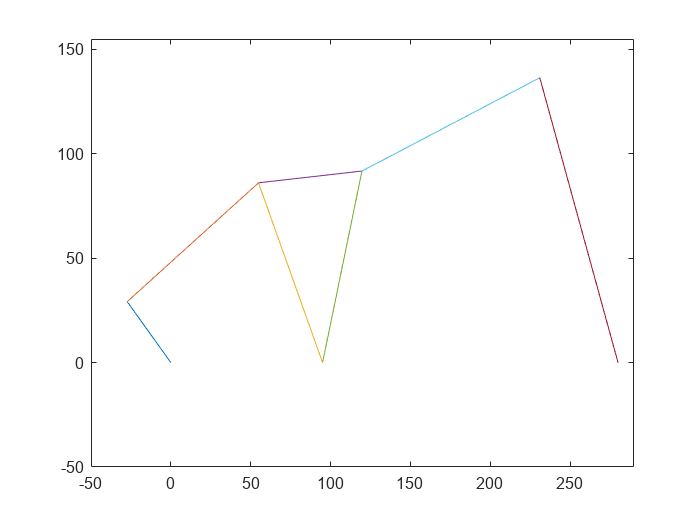

for i = 1:length(theta_values{1})
    pause(0);
    clf();
    rb_ = subs(rb, theta2, theta_values{1}(i));
    rbc_ = subs(rbc, theta3, theta_values{2}(i));
    % rce_ = subs(rce, theta4, theta_values{3}(i));
    rch_ = subs(rch, theta4, theta_values{3}(i));
    % rdf_ = subs(rdf, theta6, theta_values{5}(i));
    rdh_ = subs(rdh, theta5, theta_values{4}(i));
    % reh_ = subs(reh, theta4, theta_values{3}(i));
    rc_ = rb_ + rbc_;
    rh_ = rc_ + rch_;
    rd_ = rh_ - rdh_;

    plot([0, rb_(1)], [0, rb_(2)]);
    hold on;
    plot([rb_(1), rc_(1)], [rb_(2), rc_(2)]);
    hold on;
    plot([rc_(1), re(1)], [rc_(2), re(2)]);
    hold on;
    plot([rc_(1), rh_(1)], [rc_(2), rh_(2)]);
    hold on;
    plot([re(1), rh_(1)], [re(2), rh_(2)]);
    hold on;
    plot([rh_(1), rd_(1)], [rh_(2), rd_(2)]);
    hold on;
    plot([rd_(1), rf(1)], [rd_(2), rf(2)]);
    hold off;
    xlim([-AB - 10, AF + 10]);
    ylim([-AB - 10, DF + 10]);
end

syms f12x f12y f32x f32y f43x f43y f14x f14y f54x f54y f65x f65y f16x f16y T12;
g = 9.80665;

f12 = [f12x, f12y, 0];
f32 = [f32x, f32y, 0];
f43 = [f43x, f43y, 0];
f14 = [f14x, f14y, 0];
f54 = [f54x, f54y, 0];
f65 = [f65x, f65y, 0];
f16 = [f16x, f16y, 0];
T12_vec = [0, 0, T12];

m2g = AB * g * 1E-3 .* [0, -1, 0];
m3g = BC * g * 1E-3 .* [0, -1, 0];
s = (CE + CH + EH) / 2;
m4g = sqrt(s * (s - CE) * (s - CH) * (s - EH)) * g * 1E-6 .* [0, -1, 0];
m5g = DH * g * 1E-3 .* [0, -1, 0];
m6g = DF * g * 1E-3 .* [0, -1, 0];
p1 = [-200, 0, 0];
p2 = [0, 200, 0];
p3 = [-200, 0, 0];
T16_vec = [0, 0, T16];

m2a = AB * 1E-3 .* (cross([0, 0, omega2], cross([0, 0, omega2], rb / 2)) + cross([0, 0, alpha2], rb / 2));
m3a = BC * 1E-3 .* (cross([0, 0, omega3], cross([0, 0, omega3], rb + rbc / 2)) + cross([0, 0, alpha3], rb + rbc / 2));
rg4 = (re + rb + rbc + rb + rbc + rch) ./ 3;
m4a = sqrt(s * (s - CE) * (s - CH) * (s - EH)) * 1E-6 .* (cross([0, 0, omega4], cross([0, 0, omega4], rg4)) + cross([0, 0, alpha4], rg4));
m5a = DH * 1E-3 .* (cross([0, 0, omega5], cross([0, 0, omega5], rf - rdf + rdh / 2)) + cross([0, 0, alpha5], rf - rdf + rdh / 2));
m6a = DF * 1E-3 .* (cross([0, 0, omega6], cross([0, 0, omega6], rf - rdf / 2)) + cross([0, 0, alpha6], rf - rdf / 2));

i2alpha = 1/12 * (AB * 1E-3)^3 .* [0, 0, alpha2];
i3alpha = 1/12 * (BC * 1E-3)^3 .* [0, 0, alpha3];
B = EH;
A = dot(-rce, reh) / norm(reh);
H = sqrt(CE^2 - A^2);
I4 = (B^3 * H - B^2 * H * A + B * H * A^2 + B * H^3) / 36 * 1E-6;
i4alpha = I4 .* [0, 0, alpha4];
i5alpha = 1/12 * (DH * 1E-3)^3 .* [0, 0, alpha5];
i6alpha = 1/12 * (DF * 1E-3)^3 .* [0, 0, alpha6];

eqns_force = [
        f12 + f32 + m2g == m2a;
        cross(-rb / 2, f12) + cross(rb / 2, f32) + T12_vec == i2alpha;

        -f32 + p1 + m3g + f43 == m3a;
        cross(-rbc / 2, -f32) + cross(rbc / 2, f43) == i3alpha;

        -f43 + f14 + f54 + p2 + m4g == m4a;
        cross(re - rg4, f14) + cross(rb + rbc - rg4, -f43) + cross(rb + rbc + rch - rg4, f54) == i4alpha;

        -f54 + m5g + f65 == m5a;
        cross(-rdh / 2, f65) + cross(rdh / 2, -f54) == i5alpha;

        -f65 + p3 + m6g + f16 == m6a;
        cross(-rdf / 2, -f65) + cross(rdf / 2, f16) + T16_vec == i6alpha;
        ];

new_eqns_force = [];

for i = 1:size(eqns_force, 1)

    for j = 1:size(eqns_force, 2)

        if ~isequal(eqns_force(i, j), sym('0') == sym('0'))
            new_eqns_force = [new_eqns_force, eqns_force(i, j)];
        end

    end

end

eqns_force = new_eqns_force;

[A, Y] = equationsToMatrix(eqns_force, [f12x f12y f32x f32y f43x f43y f14x f14y f54x f54y f65x f65y f16x f16y T12]);
A

Y

X = A \ Y;
f12x_ = X(1);
f12y_ = X(2);
f32x_ = X(3);
f32y_ = X(4);
f43x_ = X(5);
f43y_ = X(6);
f14x_ = X(7);
f14y_ = X(8);
f54x_ = X(9);
f54y_ = X(10);
f65x_ = X(11);
f65y_ = X(12);
f16x_ = X(13);
f16y_ = X(14);
T12_ = X(15);
f43_values = [];
f65_values = [];
f54_values = [];
T12_values = [];


for i = 1:length(t_range)
    f43xt = vpa(subs(f43x_, [theta2, theta3, theta4, theta5, theta6, omega2, omega3, omega4, omega5, omega6, alpha2, alpha3, alpha4, alpha5, alpha6], [theta_values{1}(i), theta_values{2}(i), theta_values{3}(i), theta_values{4}(i), theta_values{5}(i), omega_values{1}(i), omega_values{2}(i), omega_values{3}(i), omega_values{4}(i), omega_values{5}(i), alpha_values{1}(i), alpha_values{2}(i), alpha_values{3}(i), alpha_values{4}(i), alpha_values{5}(i)]));
    f43yt = vpa(subs(f43y_, [theta2, theta3, theta4, theta5, theta6, omega2, omega3, omega4, omega5, omega6, alpha2, alpha3, alpha4, alpha5, alpha6], [theta_values{1}(i), theta_values{2}(i), theta_values{3}(i), theta_values{4}(i), theta_values{5}(i), omega_values{1}(i), omega_values{2}(i), omega_values{3}(i), omega_values{4}(i), omega_values{5}(i), alpha_values{1}(i), alpha_values{2}(i), alpha_values{3}(i), alpha_values{4}(i), alpha_values{5}(i)]));
    f65xt = vpa(subs(f65x_, [theta2, theta3, theta4, theta5, theta6, omega2, omega3, omega4, omega5, omega6, alpha2, alpha3, alpha4, alpha5, alpha6], [theta_values{1}(i), theta_values{2}(i), theta_values{3}(i), theta_values{4}(i), theta_values{5}(i), omega_values{1}(i), omega_values{2}(i), omega_values{3}(i), omega_values{4}(i), omega_values{5}(i), alpha_values{1}(i), alpha_values{2}(i), alpha_values{3}(i), alpha_values{4}(i), alpha_values{5}(i)]));
    f65yt = vpa(subs(f65y_, [theta2, theta3, theta4, theta5, theta6, omega2, omega3, omega4, omega5, omega6, alpha2, alpha3, alpha4, alpha5, alpha6], [theta_values{1}(i), theta_values{2}(i), theta_values{3}(i), theta_values{4}(i), theta_values{5}(i), omega_values{1}(i), omega_values{2}(i), omega_values{3}(i), omega_values{4}(i), omega_values{5}(i), alpha_values{1}(i), alpha_values{2}(i), alpha_values{3}(i), alpha_values{4}(i), alpha_values{5}(i)]));
    f54xt = vpa(subs(f54x_, [theta2, theta3, theta4, theta5, theta6, omega2, omega3, omega4, omega5, omega6, alpha2, alpha3, alpha4, alpha5, alpha6], [theta_values{1}(i), theta_values{2}(i), theta_values{3}(i), theta_values{4}(i), theta_values{5}(i), omega_values{1}(i), omega_values{2}(i), omega_values{3}(i), omega_values{4}(i), omega_values{5}(i), alpha_values{1}(i), alpha_values{2}(i), alpha_values{3}(i), alpha_values{4}(i), alpha_values{5}(i)]));
    f54yt = vpa(subs(f54y_, [theta2, theta3, theta4, theta5, theta6, omega2, omega3, omega4, omega5, omega6, alpha2, alpha3, alpha4, alpha5, alpha6], [theta_values{1}(i), theta_values{2}(i), theta_values{3}(i), theta_values{4}(i), theta_values{5}(i), omega_values{1}(i), omega_values{2}(i), omega_values{3}(i), omega_values{4}(i), omega_values{5}(i), alpha_values{1}(i), alpha_values{2}(i), alpha_values{3}(i), alpha_values{4}(i), alpha_values{5}(i)]));
    T12t = vpa(subs(T12_, [theta2, theta3, theta4, theta5, theta6, omega2, omega3, omega4, omega5, omega6, alpha2, alpha3, alpha4, alpha5, alpha6], [theta_values{1}(i), theta_values{2}(i), theta_values{3}(i), theta_values{4}(i), theta_values{5}(i), omega_values{1}(i), omega_values{2}(i), omega_values{3}(i), omega_values{4}(i), omega_values{5}(i), alpha_values{1}(i), alpha_values{2}(i), alpha_values{3}(i), alpha_values{4}(i), alpha_values{5}(i)]));

    f43_values = [f43_values, sqrt(f43xt^2 + f43yt^2)];
    f65_values = [f65_values, sqrt(f65xt^2 + f65yt^2)];
    f54_values = [f54_values, sqrt(f54xt^2 + f54yt^2)];
    T12_values = [T12_values, T12t];
end

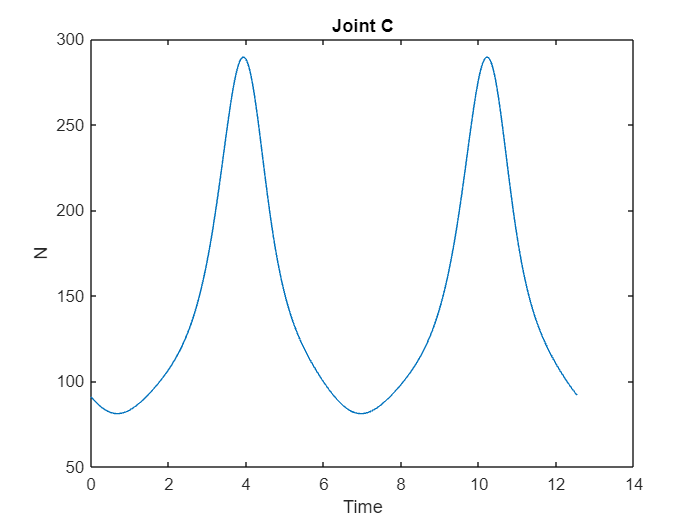

figure;
plot(t_range, f43_values);
title('Joint C');
xlabel('Time');
ylabel('N');

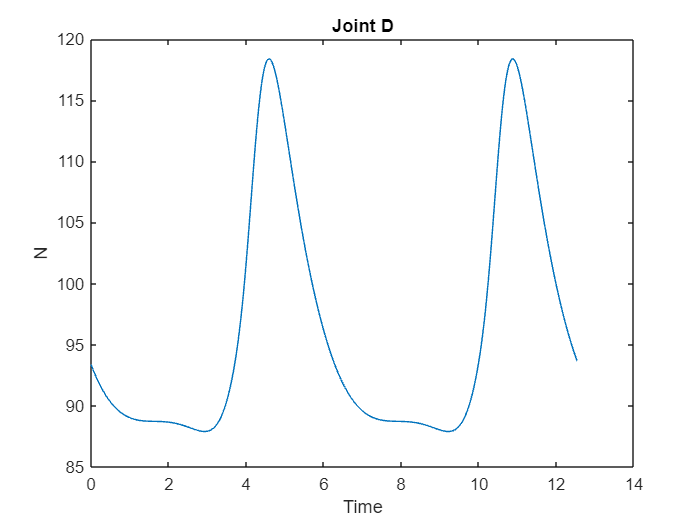

figure;
plot(t_range, f65_values);
title('Joint D');
xlabel('Time');
ylabel('N');

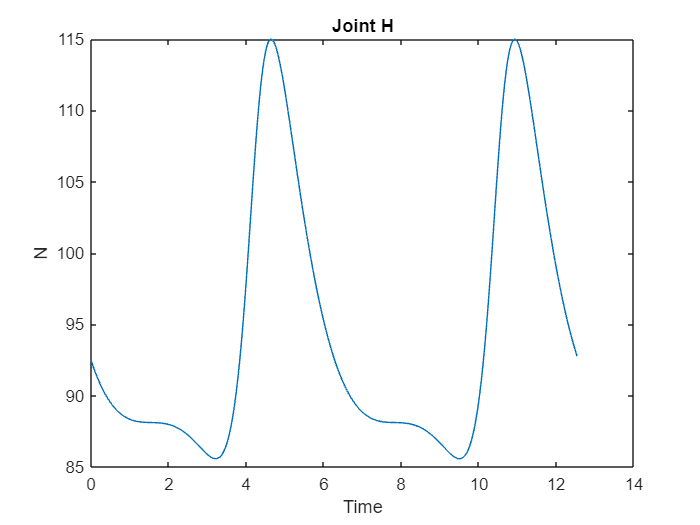

figure;
plot(t_range, f54_values);
title('Joint H');
xlabel('Time');
ylabel('N');

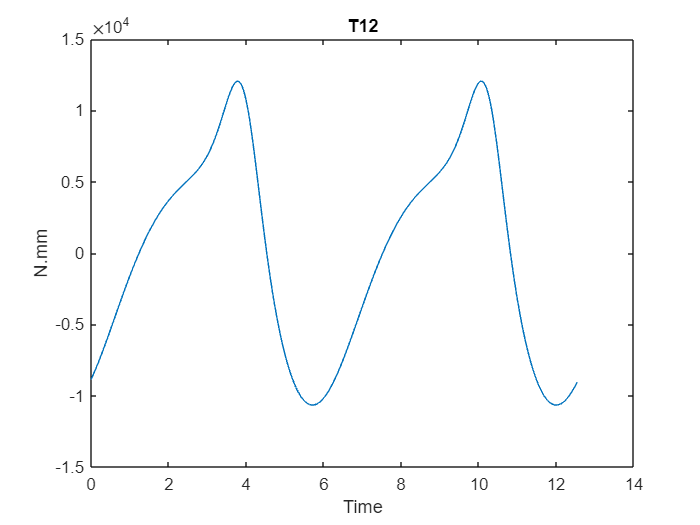

figure;
plot(t_range, T12_values);
title('T12');
xlabel('Time');
ylabel('N.mm');